# Lab 4: Pendulum Experiment

Pendulum Released at 30°

load('30_deg.log') % read data

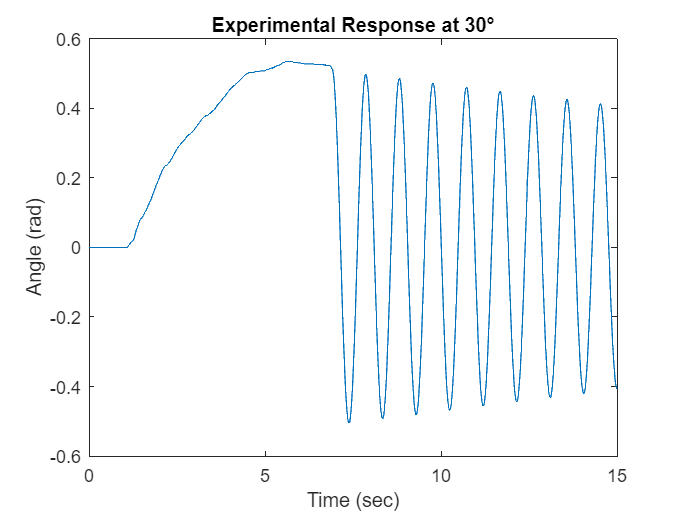

% parse data into vectors
time = X30_deg(:, 1);
encoder = X30_deg(:, 2);

% convert encoder count into radians
degrees = encoder * (360/4096);
radians = deg2rad(degrees);

time = time - 33; % start at t=0

interval = find(time > 0 & time < 15); % set interval

% plot data
plot(time(interval), radians(interval))
title("Experimental Response at 30°")
xlabel("Time (sec)")
ylabel("Angle (rad)")

Pendulum Released at 15°

load('15_deg.log') % read data

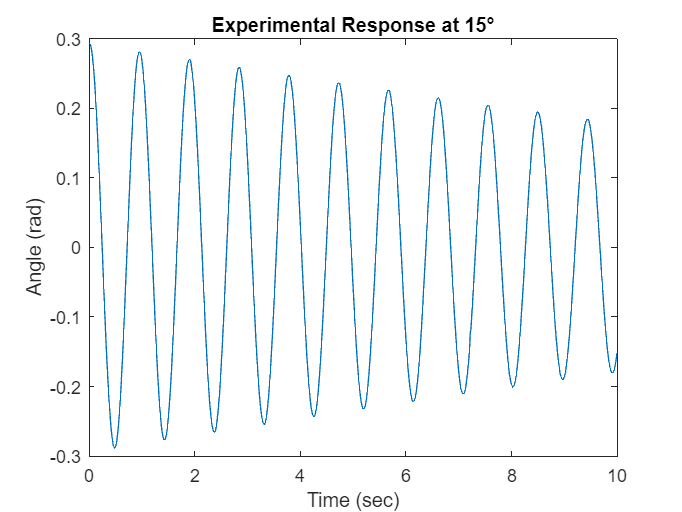

% parse data into vectors
time = X15_deg(:, 1);
encoder = X15_deg(:, 2);

% convert encoder count into radians
degrees = encoder * (360/4096);
radians = deg2rad(degrees);

% start at drop height
start = find(radians == max(radians), 1);
time = time - time(start);

interval = find(time > 0 & time < 10); % set interval

% plot data
plot(time(interval), radians(interval))
title("Experimental Response at 15°")
xlabel("Time (sec)")
ylabel("Angle (rad)")

Calculate frequency of oscillation, damping ratio, and natural frequency

interval = find(time > 0 & time < 6); % create smaller interval 
[pks, locs] = findpeaks(radians(interval)); % find peaks 
T = mean(diff(time(locs))); % calculate average period
w_d = (2*pi)/T % calculate frequency of oscillation

w_d = 6.8970

z = []; % initialize zeta
for i = 1:length(pks)-1
    z(i) = log(pks(i)/pks(i+1)) / sqrt(4*pi^2 + (log(pks(i)/pks(i+1))^2)); % calculate zeta
end

zeta = mean(z) % calculate average zeta 

zeta = 0.0070

w_n = w_d / sqrt(1 - zeta^2) % calculate natural frequency 

w_n = 6.8972

% coefficients
m = 0.128; % kg
g = 9.81; % m/s^2
L = 0.34; % m
J = (1/3)*m*L*L; % kg m^2

b = 2*zeta*w_n*J

b = 4.7439e-04

Non-linear Simulation

% initial conditions
theta_dot = 0; % rad/s
theta = radians(interval(1)); % rad

Simulate

% run the non-linear simulation
out = sim('Pendulum_Simulink.slx', 10);

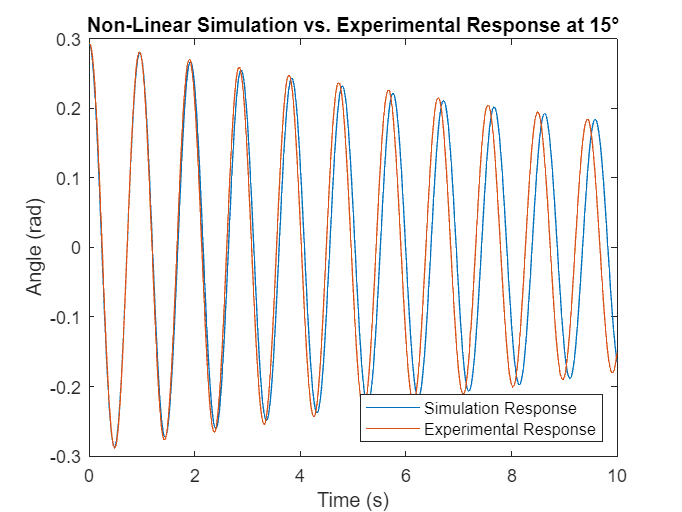

interval = find(time > 0 & time < 10); % set interval

% plot response
plot(out.theta.Time, out.theta.Data)
hold on 
plot(time(interval), radians(interval))
hold off
title("Non-Linear Simulation vs. Experimental Response at 15°")
xlabel("Time (s)")
ylabel("Angle (rad)")
legend("Simulation Response", "Experimental Response", 'Location', 'southeast')

Pendulum Released at 20°

X20_deg = readtable('20_deg.log'); % read data

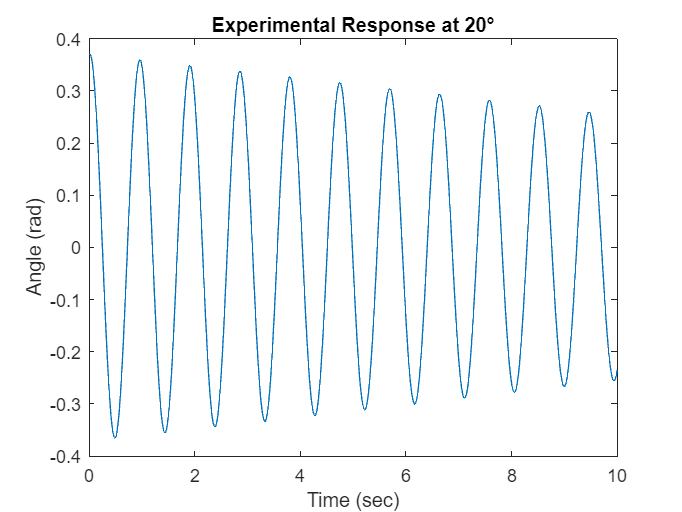

% parse data into vectors
time = X20_deg.Var1;
encoder = X20_deg.Var2;

% convert encoder count into radians
degrees = encoder * (360/4096);
radians = deg2rad(degrees);

% start a little before drop height
start = find(radians == max(radians), 1);
time = time - time(start);

interval = find(time > 0 & time < 10); % set interval

% plot data
plot(time(interval), radians(interval))
title("Experimental Response at 20°")
xlabel("Time (sec)")
ylabel("Angle (rad)")

Non-linear Simulation

% initial conditions
theta_dot = 0; % rad/s
theta = radians(interval(1)); % rad

Simulate

% run the non-linear simulation
out = sim('Pendulum_Simulink.slx', 10);

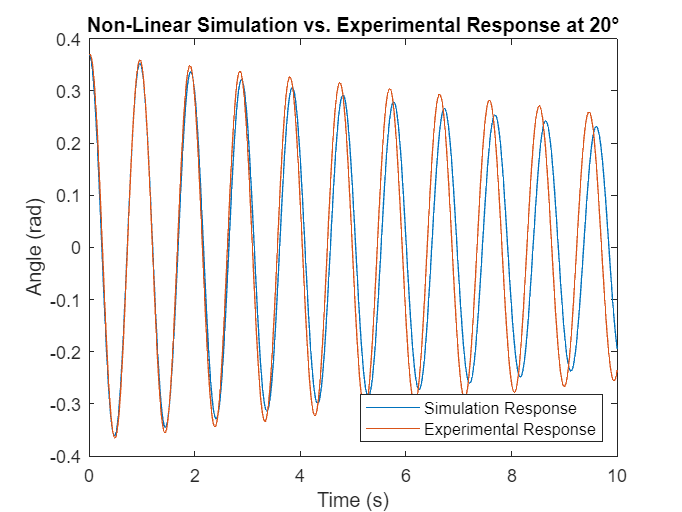

% plot response
plot(out.theta.Time, out.theta.Data)
hold on 
plot(time(interval), radians(interval))
hold off
title("Non-Linear Simulation vs. Experimental Response at 20°")
xlabel("Time (s)")
ylabel("Angle (rad)")
legend("Simulation Response", "Experimental Response", 'Location', 'southeast')